
$$y_{n+1}=y_n+\frac{h}{6}(K_1+2K_2+2K_3+K_4)$$



$$K_1=f(x_n,y_n)$$



$$K_2=f(x_n+\frac{h}{2}，y_n+\frac{h}{2}K_1)$$



$$K_3 = f(x_n+\frac{h}{2},y_n+\frac{h}{2}K_2)$$



$$K_4=f(x_n+h,y_n+hK_3)$$


clc,clear,close all

f = @(x,y) y-x^2+1;             % 设置微分方程
a = 0;                          % 区间左端点
b = 2;                          % 区间右端点
h = 0.2;                        % 取点间隔
x = a:h:b;                      % x_i
n = length(x)-1;                % n
y = zeros(1,n+1);               % 预分配内存
y(1) = 0.5;                       % 设置初始值

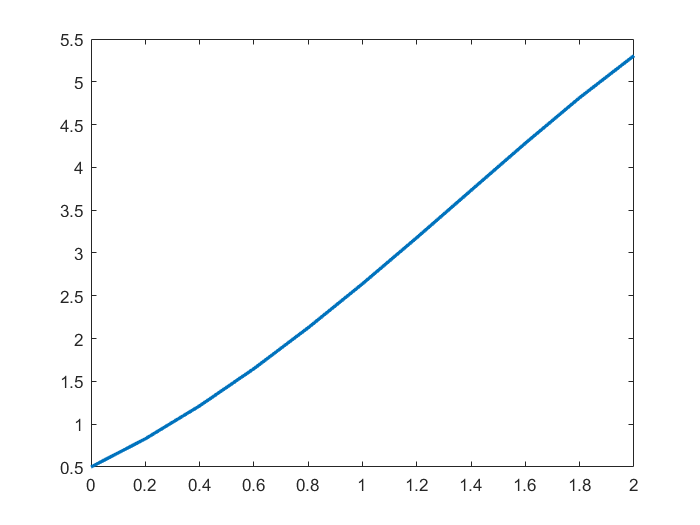

%% 利用龙格库塔法求解微分方程
for i = 1:n
    K_1 = f(x(i),y(i));
    K_2 = f(x(i)+h/2,y(i)+h/2*K_1);
    K_3 = f(x(i)+h/2,y(i)+h/2*K_2);
    K_4 = f(x(i)+h,y(i)+h*K_3);
    
    delta = (K_1+2*K_2+2*K_3+K_4)/6;
    y(i+1) = y(i) + delta*h;
end

%% 绘制图像
plot(x,y,'linewidth',2)

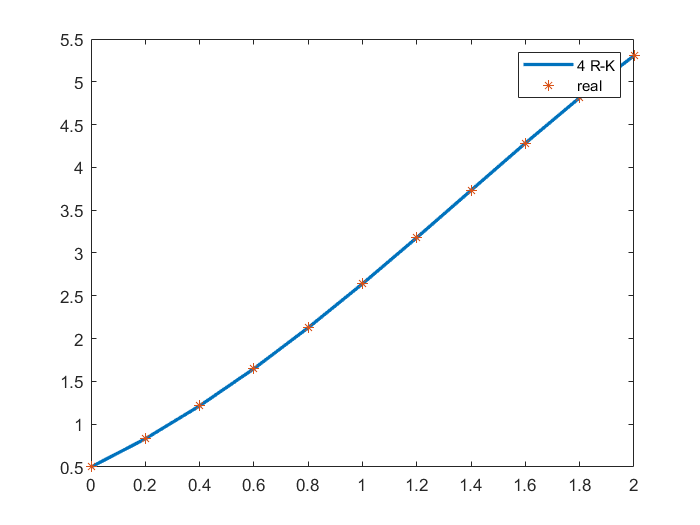

% 这里的函数 f 是题目函数 y 的解析解
% 将 x_i 带入解析解中并作图验证求解是否准确
f = @(x) 2*x-exp(x)/2+x.^2+1;
y_real = f(x);
hold on
plot(x,y_real,'*')
xlim([a,b])
legend('4 R-K','real')